# Exam F21

## Question 1

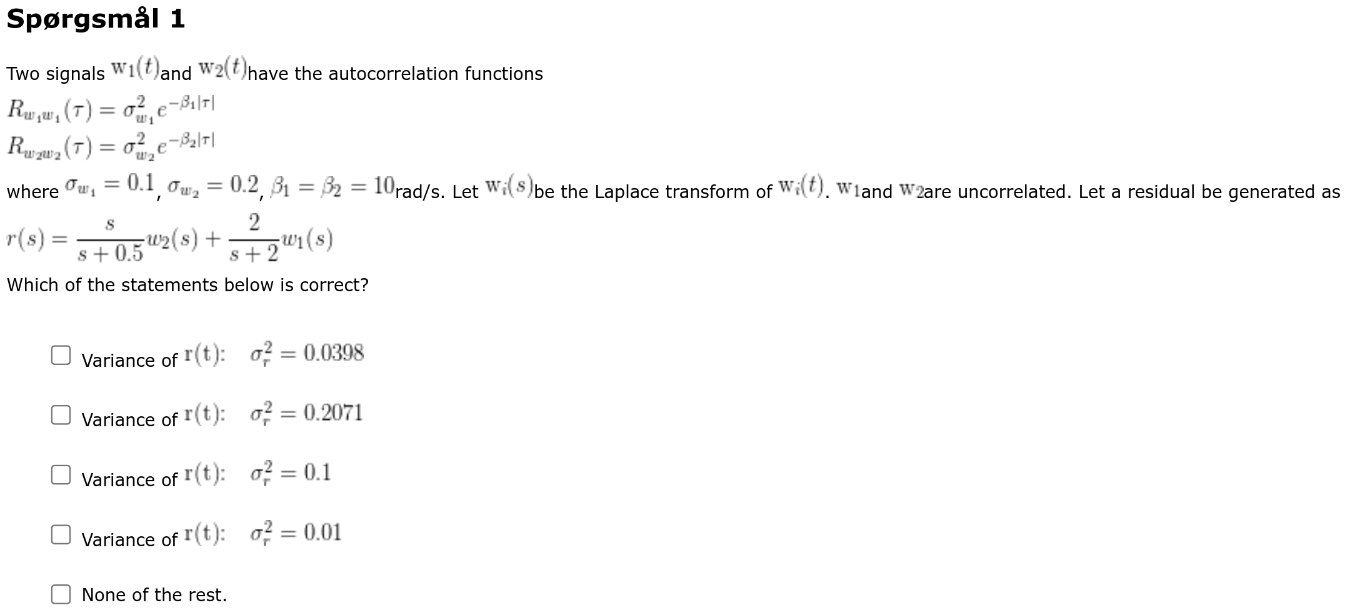

syms beta1 beta2
sigma1 = 0.1^2; sigma2 = 0.2^2;
r1 = subs((2/(beta1 + 2))*sigma1, beta1, 10);
r2 = subs((beta2/(beta2 + 0.5))*sigma2, beta2, 10);
vpa(r1 + r2, 3)

$$ans = 0.0398$$

## Question 2

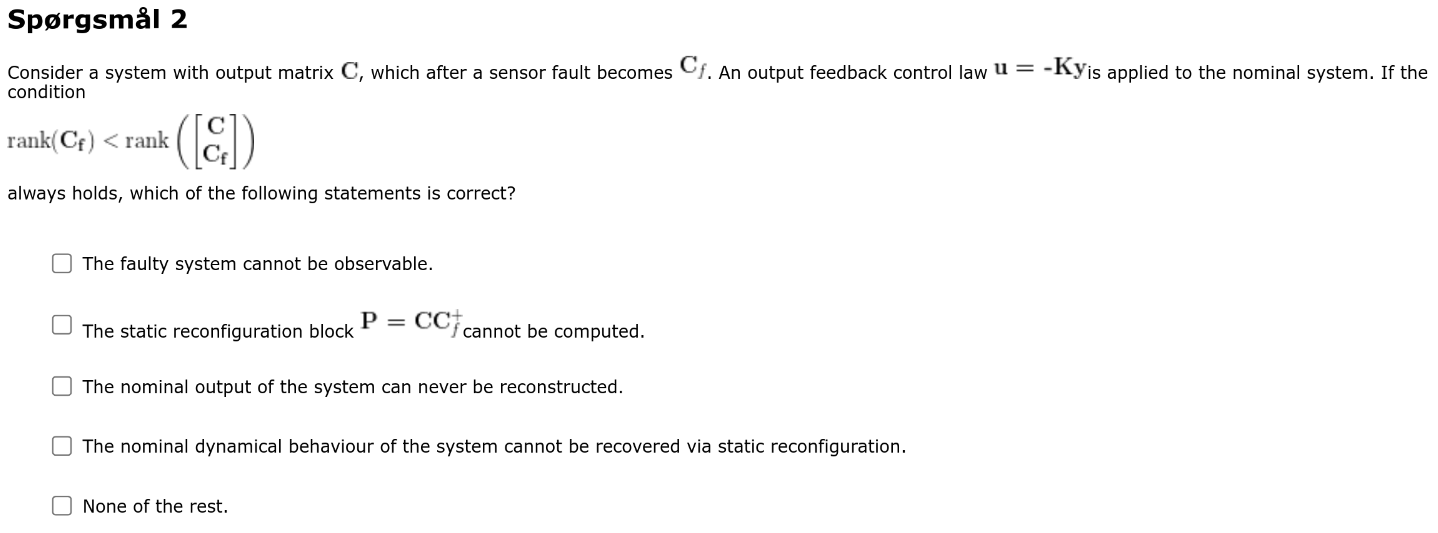

Option 4. Same as F20.

## Question 3

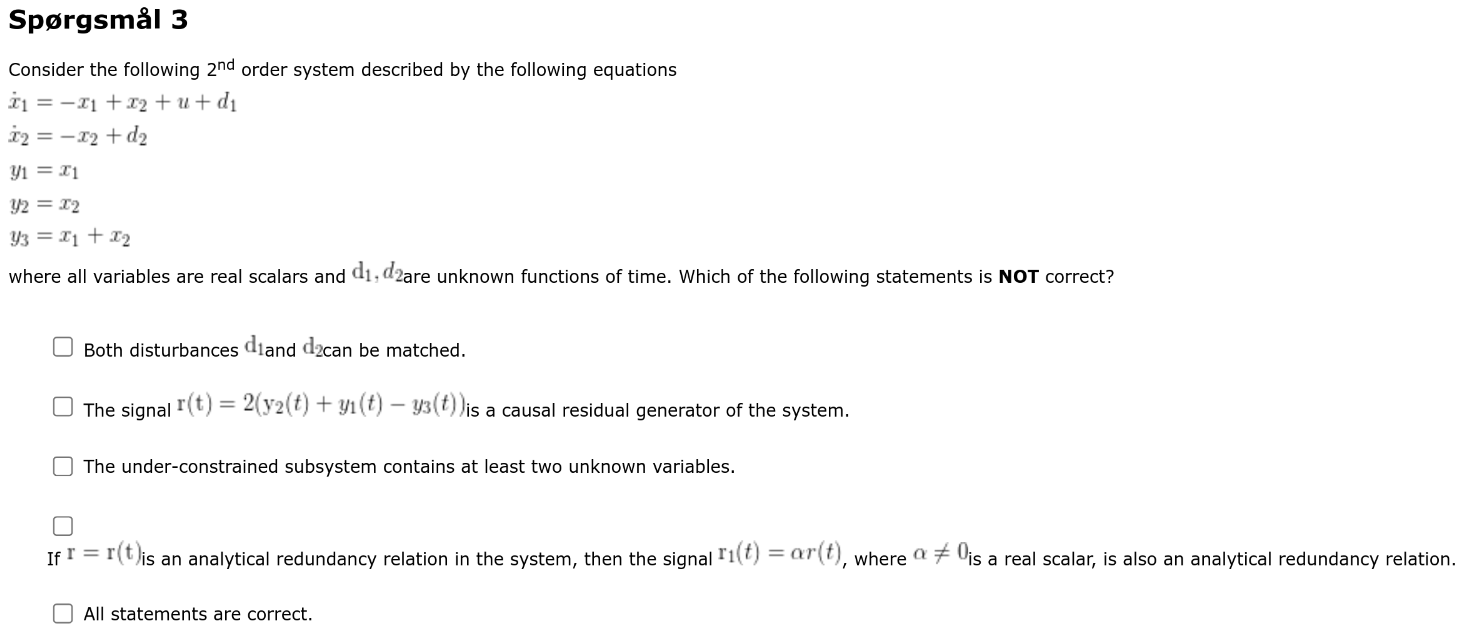

clear all;
close all;
clc;
syms u1(t) % Symbolic input declaration
ST_input(1,:) = {u1}; % symbolic variable
% Measurements
syms y1(t) y2(t) y3(t) % Symbolic measurement declaration
ST_meas(1,:) = {y1, y2 y3}; % symbolic variable
% Unknowns
syms x1(t) x2(t) dx1(t) dx2(t) d1(t) d2(t)  %Symbolic unknowns declaration
ST_unknowns(1,:) = {x1, x2, dx1, dx2, d1, d2}; % symbolic variable

ST_cons(1,:) = {'c1','c2','c3','c4','c5', 'd6', 'd7'}; % Constraint names
ST_cons(3,:) = {...
                0 == -dx1 - x1 + u1 + d1,...
                0 == -x2 + d2,...
                0 == x1 - y1,...
                0 == x2 - y2,...
                0 == x1 + x2 - y3,...
                0 == diff(x1,t) - dx1,...
                0 == diff(x2,t) - dx2};

% NOTE that "diff(.,t)" is used as the differential operator, D == d/dt.
ST_canfail  = [1:5]; % constraint d7-d12 cannot fail
ST_domains  = [1 1 1 1 1 1 1];


% Automatic incMatrix generation
cons_oneway = {[],[],[],[], [], {x1}, {x2}};
ST_IncMat = sa_incidencematrix(ST_cons,...
    ST_input,ST_meas,...
    ST_unknowns,cons_oneway);

% disp(ST_IncMat)

ST_sys =...
    sa_create(ST_IncMat,ST_cons,...
    ST_input, ST_meas,ST_unknowns,...
    ST_domains, ST_canfail);

sa_disp(ST_sys);

System with 7 constraint(s), 1 input(s), 3 measurement(s) and
            7 unknown variable(s).
Unused variable(s)    : dy1.


ST_sys=sa_match(ST_sys,'rank'); % alternatively 'rank' MSO

disp('Obtained matching:');

Obtained matching:


sa_disp(ST_sys, 't')

  |     c1 |     c2 |     c3 |     c4 |     c5 |     d6 |     d7
----------------------------------------------------------------
1 |  d1(t) |  d2(t) |  x1(t) |  x2(t) |      0 | dx1(t) | dx2(t)



disp('Parity relation symbolic form:')

Parity relation symbolic form:


sa_disp(ST_sys, 's')

Matching 1:
  c5(y3,c3(y1),c4(y2))



disp('Parity relation analytic form:')

Parity relation analytic form:


sa_disp(ST_sys, 'a')

Matching 1:
  0 == y1(t) + y2(t) - y3(t)



pretty(y1(t) + y2(t) - y3(t))

y1(t) + y2(t) - y3(t)



Under constrained: constraints < unknown variables

Just constrained: constraints == unknown variables

Over constrained: constraints > unknown variables

## Question 4

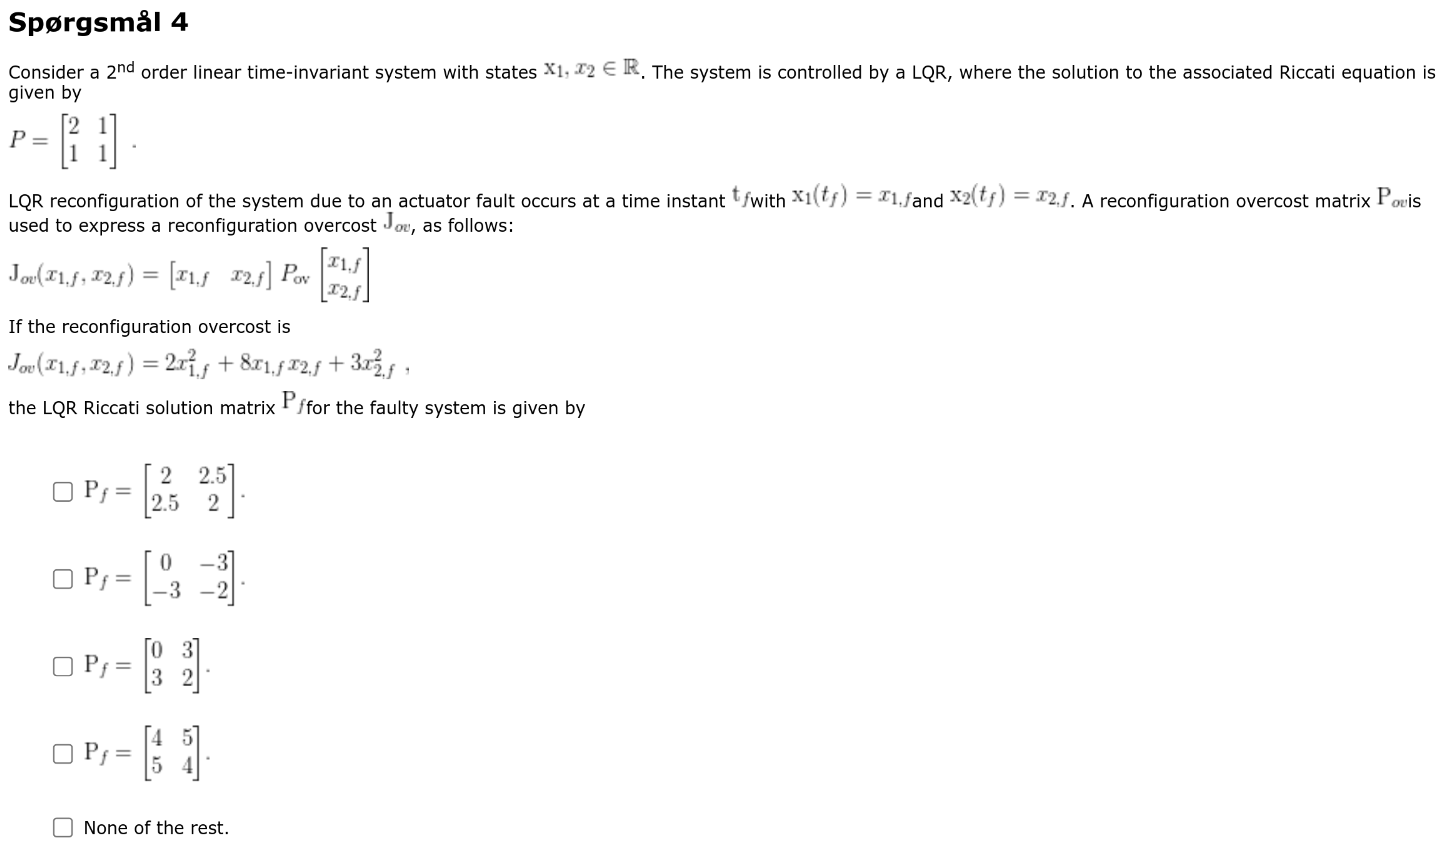

## Question 5

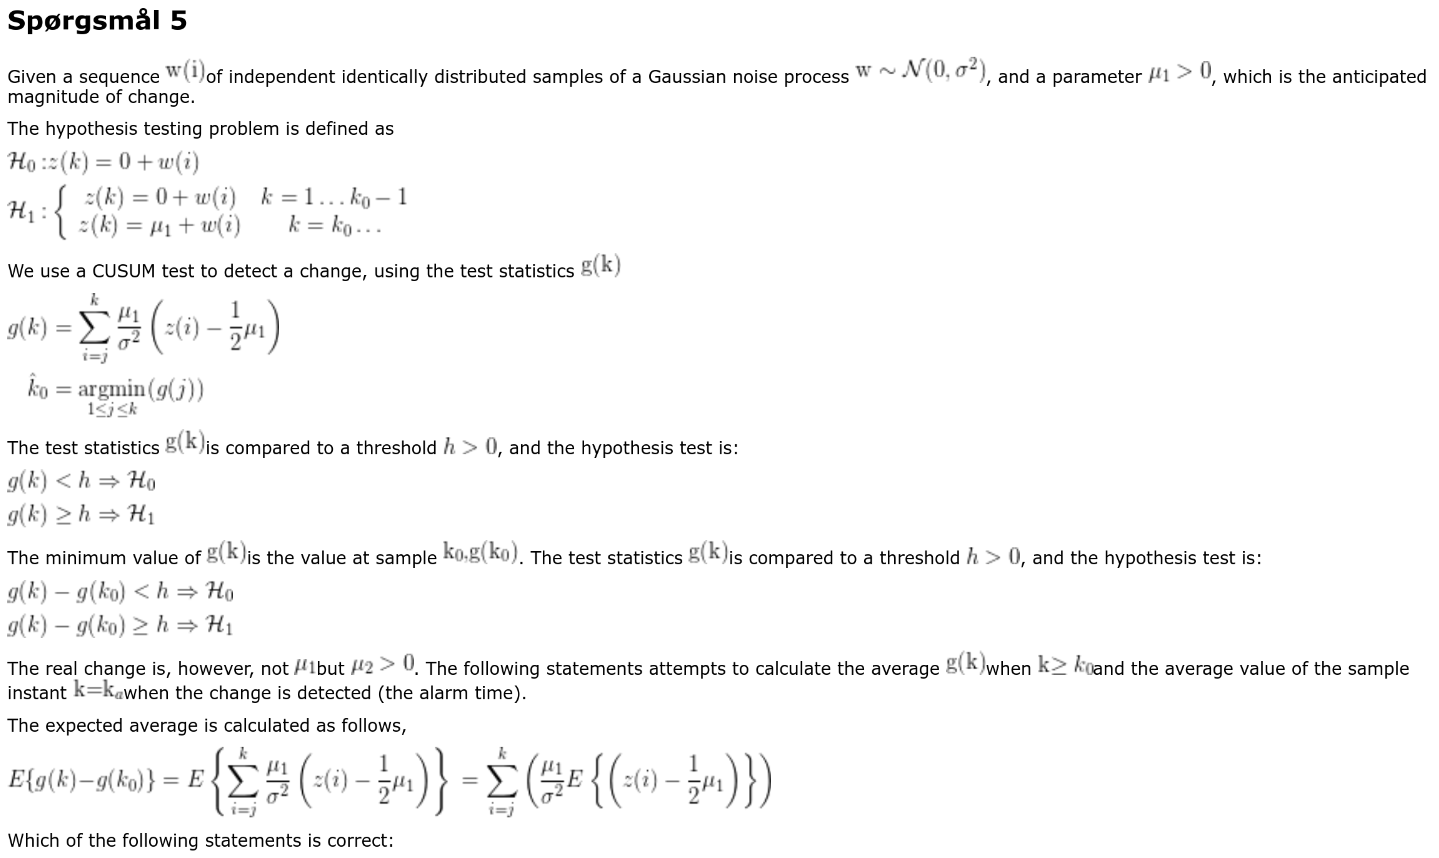

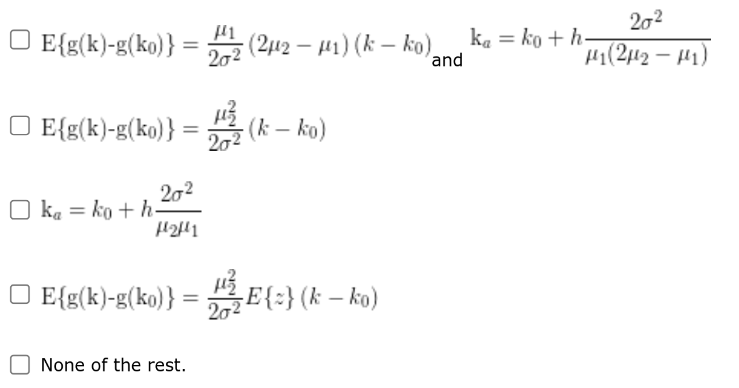

## Question 6

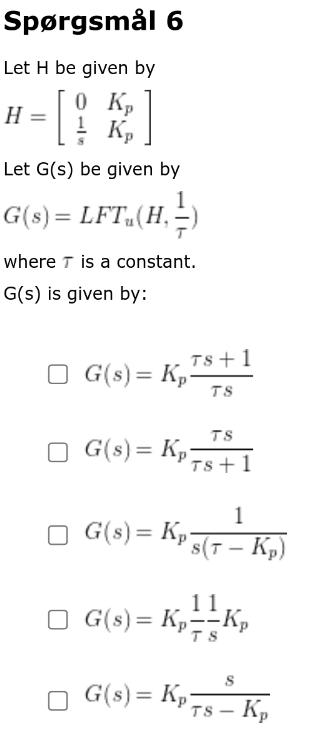

## Question 7

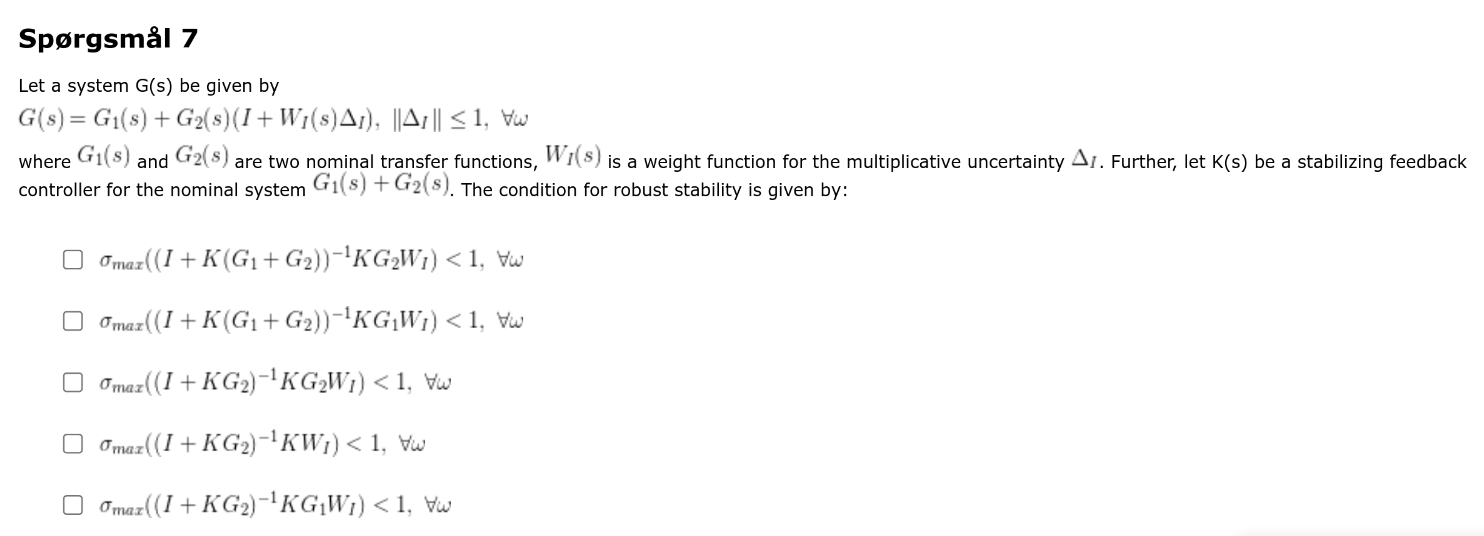

## Question 8

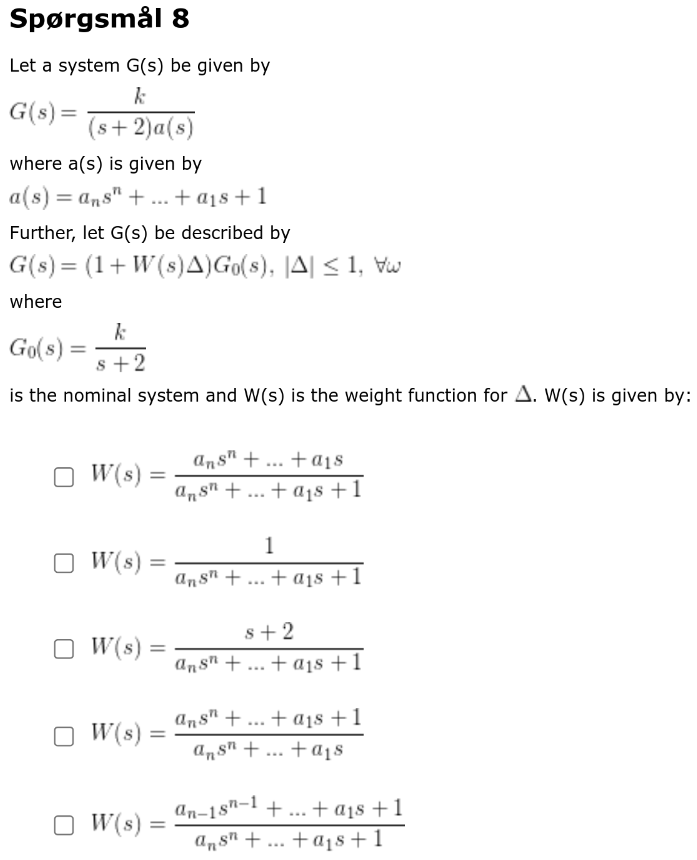

## Question 9

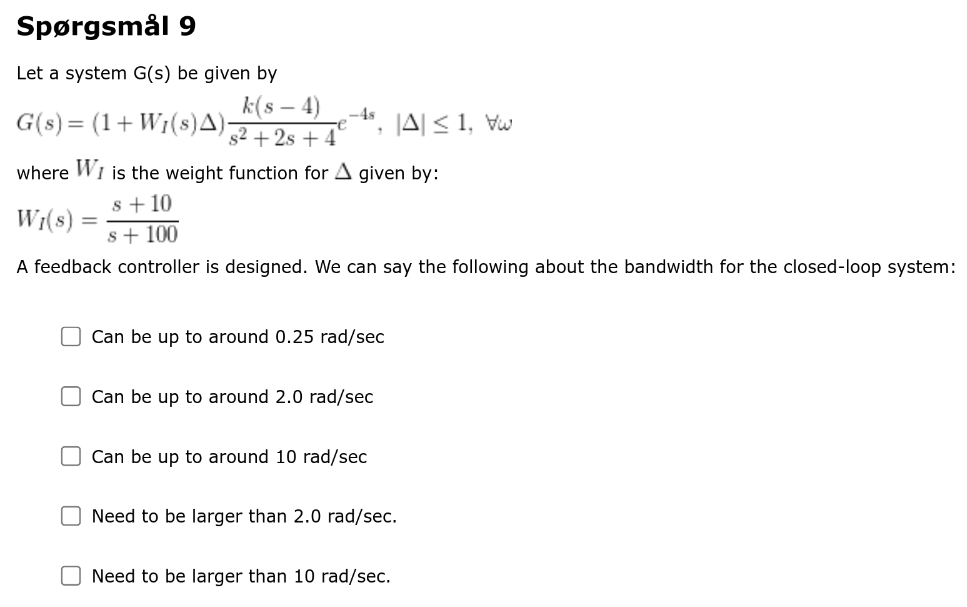

## Question 10